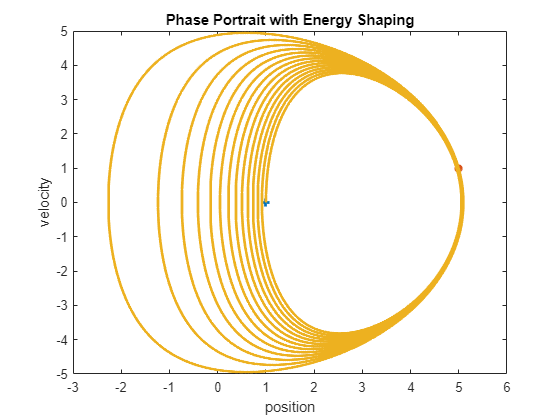

clc;clear;close all;

tfinal = 50; dt = 0.001; % simulation parameters
k = 1; m = 1;
A_PHS = [0 1/m;-k 0]; B_PHS = [0; 1];
x_des = 5; v_des=1; lambda = -2;

x0 = [1;0]; x = x0; t = 0; 
p0 = m*x(2); p = p0;        % momentum
q0 = x(1); q = q0;          % position
Z0 = [q0; p0];
Z = Z0;

PHS = [];                   % initialize memory
while (t <= tfinal)
    PHS = [PHS,Z];

    H_sys = p^2/(2*m) + (k*q^2)/2;
    E_error = H_sys - (k*x_des^2/2 + m*v_des^2/2);
    if abs(E_error)<1e-4
        lambda = 0;
    end
    u = 0.5*lambda*(E_error);
    Z = Z + dt*((A_PHS*Z + B_PHS*u));
    p = Z(2)/m; q = Z(1);
    t = t + dt; % time increment
end



figure
plot(x0(1),x0(2),'+', x_des, v_des, '*', PHS(1,:),PHS(2,:),LineWidth=2);
ylabel('velocity')
xlabel('position')
title('Phase Portrait with Energy Shaping')